# Plot angular distributions

May 2020 by Ercag

Revised on October 2021 by Ercag

clearvars;
close all;

## Define Export Path for figures

ExpPath = 'C:\Users\ercagp\Box\Research\VibrioFischeri_Project\Data\AngularAnalysis';
if ~exist(ExpPath,'dir')
    mkdir(ExpPath);
end

## Call the run reverse analysis files

MainPath = 'C:\Users\ercagp\Documents\Rowland_Data\RunReverseAnalysis\RunReverse_Data';
StrainLabels = {'KMT47'};
Lambda = 0.5;

## Define Histogram Parameters

%Define bins
HistPara.Bins = 0:2:180; 
HistPara.LineWidth = 0.5; 
%Selected IPTG value
HistPara.IPTGSel = 25; %[uM]
HistPara.Normalization = 'count';
HistPara.NormSwitch = 'Normalized'; 
HistPara.DisplayStyle = 'Bar'; 
HistPara.Label.XAx = 'Turn Angle (degrees)';
if strcmp(HistPara.NormSwitch,'PDF')
   HistPara.Label.YAx = 'PDF'; 
else
   HistPara.Label.YAx = 'Counts';
end
HistPara.Lim.X = [0, 180];

## Define Density Plot Parameters

hf =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


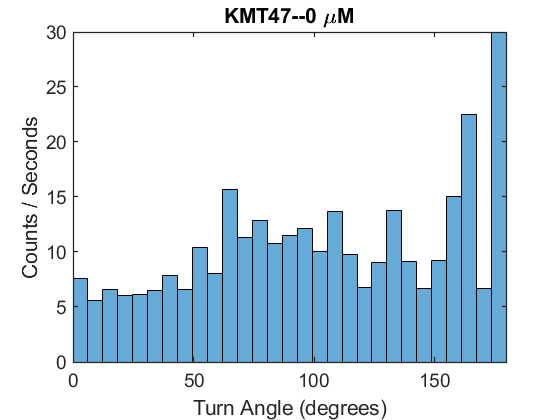

hf =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


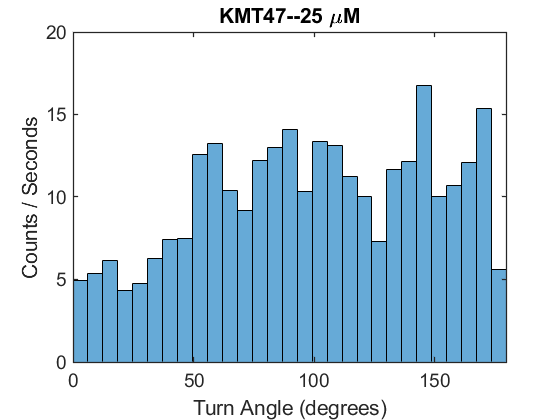

hf =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


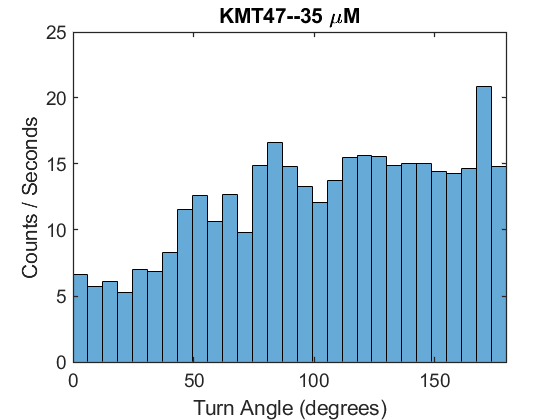

hf =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


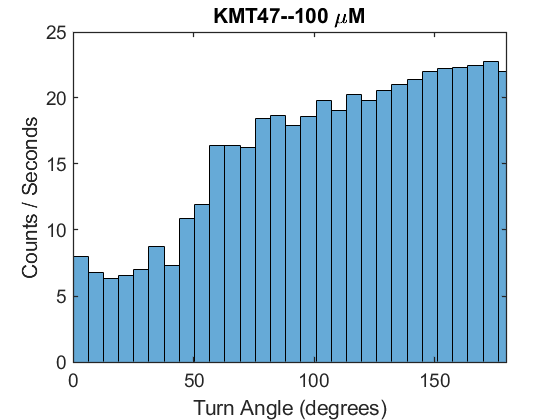

hf =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


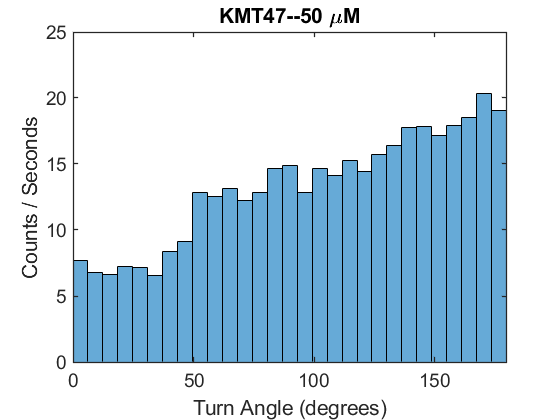

hf =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


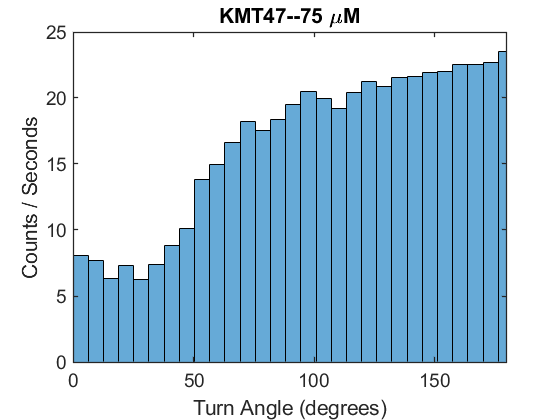

hf =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


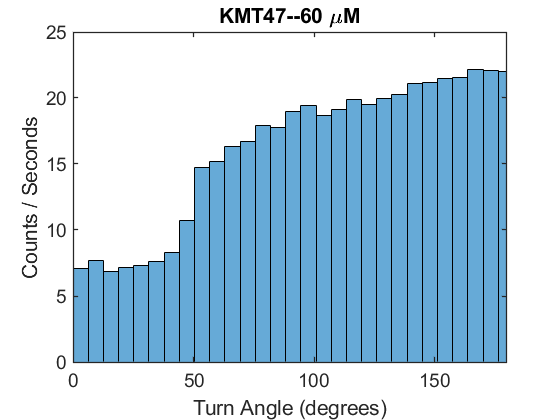

hf =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


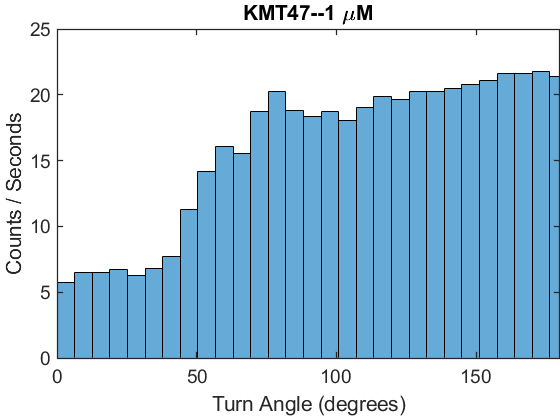

DensityPlotPara.XEdge = 0:2:180;
DensityPlotPara.YEdge = 0:2:180;
DensityPlotPara.DisplayStyle = 'tile';
DensityPlotPara.Normalization = 'PDF'; 

fps = 30; %Hz

for j = 1:length(StrainLabels) 
    %Find .mat files
    Files = callResultsv2(MainPath, StrainLabels{j},Lambda);
    %Preallocate
    IPTG = zeros(length(Files),1);
    TurnAngle = cell(length(Files),1);
    AngleBefore = cell(length(Files),1);
    AngleAfter = cell(length(Files),1);
    EventRate = zeros(length(Files),1);
    Turns = cell(length(Files),1);

    for i = 1:length(Files) 
        load(Files{i}) 
        IPTG(i) = RunReverse.Info.IPTG;
        TurnAngle{i} = Results.Ang(:,3); %note: all turn angles are already filtered
        AngleBefore{i} = TurnAngle{i}(1:end-1); 
        AngleAfter{i} = TurnAngle{i}(2:end); 
        EventRate(i) = RunReverse.EventRate;
        Turns{i} = TurnBreakDown(Speeds,Results.T,Results.minV,Results.minT,fps);
               
        [SpeedsFlt,FiltMask] = filterout(Speeds,Results.minT,Results.minV,fps);
    end
    
    TurnA = matchrepeat(IPTG,TurnAngle);
    AngleBR = matchrepeat(IPTG,AngleBefore); 
    AngleAR = matchrepeat(IPTG,AngleAfter); 
    EventRt = matchrepeat(IPTG,EventRate);
    TurnMatch = matchrepeat(IPTG,Turns); 
    
    
    ERavg = cellfun(@mean,EventRt(:,2));
    %Create a cell to store IPTG values for the figure's legend 
    IPTG_TurnAngle = cell(1,size(TurnA,1)); 
    %Label for the figure's title
    HistPara.Label.Title = StrainLabels{j}; 
    DensityPlotPara.StrainLabel = StrainLabels{j}; 

    %Create a cell to store histogram obj
    TurnAngleHist = cell(1,size(TurnA,1));
    
    for k = 1:size(TurnA,1)

        IPTG_TurnAngle{k} = strcat(num2str(TurnA{k,1}),' \muM'); 
        TurnAngle = TurnA{k,2}; 
        Turns = TurnMatch{k,2}; 
        
        Angle.BeforeR = AngleBR{k,2};
        Angle.AfterR = AngleAR{k,2}; 
        IPTG_AngBA = AngleBR{k,1}; 

        %hf = figure(j);
        hf = figure
        HistPara.Label.Title = [StrainLabels{j} '--' IPTG_TurnAngle{k}]; 
        %TurnAngleHist{k} = AngleDist(TurnAngle,HistPara,hf);
        TurnAngleHist{k} = AngleDist(TurnAngle,Turns,HistPara,hf);
        
        %printfig(hf,fullfile(ExpPath,['[20201119]' StrainLabels{j} '_[IPTG]' num2str(TurnA{k,1}) 'uM_NormalizedTurnAngles.pdf']),'-dpdf')
        %printfig(hf,fullfile(ExpPath,['[20201119]' StrainLabels{j} '_[IPTG]' num2str(TurnA{k,1}) 'uM_NormalizedTurnAngles.png']),'-dpng')

       
        %hold on 
        
        %hfDensityPlt = figure(3*length(StrainLabels)+k+((j-1)*size(TurnA,1)));
        
        %AngleBeforeAfterRun(Angle,IPTG_AngBA,DensityPlotPara)
        %printfig(hfDensityPlt,fullfile(ExpPath,['[20201119]' StrainLabels{j} '_[IPTG]_' num2str(IPTG_AngBA) 'uM_AngleBeforeRunAfterRun.pdf']),'-dpdf')
    end
    
    figure(hf)
    settightplot(gca); 
    %[~,LegendOrder] = sort(cell2mat(TurnA(:,1)));
    %legend([TurnAngleHist{LegendOrder}],IPTG_TurnAngle(LegendOrder),'Location','NorthWest')
    %printfig(hf,fullfile(ExpPath,['[20201119]' StrainLabels{j} '_TurnAngles.pdf']),'-dpdf')
    
end

## Functions

function DensityPlotH = AngleBeforeAfterRun(Angle,IPTG,DensityPlotPara)
        XEdge = DensityPlotPara.XEdge;
        YEdge = DensityPlotPara.XEdge;
        DisplayStyle = DensityPlotPara.DisplayStyle;
        Normalization = DensityPlotPara.Normalization; 
        StrainLabel = DensityPlotPara.StrainLabel; 
        
        
        %Data
        AngleBeforeRun = Angle.BeforeR; 
        AngleAfterRun = Angle.AfterR; 
        AngleBeforeRunPlt = AngleBeforeRun(1:length(AngleAfterRun));
        
        DensityPlotH = histogram2(AngleBeforeRunPlt,AngleAfterRun,XEdge,YEdge,'DisplayStyle',DisplayStyle,...
            'ShowEmptyBins','on','Normalization',Normalization); 
        
        colorbar
        xlabel('Turn Angle Before Run')
        ylabel('Turn Angle After Run')
        title({StrainLabel,['[IPTG] = ' num2str(IPTG) '\muM']})
end


function AnglePlotH = AngleDist(X,Turns,PltPara,hFig)
         
         Bins = PltPara.Bins;
         DisplayStyle = PltPara.DisplayStyle;
         LineWidth = PltPara.LineWidth;
         Normalization = PltPara.Normalization; 
         NormSwitch = PltPara.NormSwitch;
         SelectedIPTG = PltPara.IPTGSel;
         AxLabel = PltPara.Label; 
         Lim = PltPara.Lim;
        
        if strcmp(NormSwitch,'Normalized')
           EdgesTurn = 1/30:1/30:30*(1/30); %fps = 30 Hz; 

           [N,Edges,BinTA] = histcounts(X,length(EdgesTurn)-1);
           [~, EdgesT,~] = histcounts(Turns,EdgesTurn);
          
            for i = 1:length(EdgesT)-1
                TotalTurnBin(i) = sum(Turns(BinTA == i));
                if TotalTurnBin(i) == 0 
                    %Skip normalization
                    N_Norm(i) = N(i);
                else
                    N_Norm(i) = N(i) / TotalTurnBin(i);
                end
            end
           
            
           AnglePlotH = histogram('BinEdges',Edges,'BinCounts',N_Norm,'DisplayStyle',DisplayStyle,...
                                 'LineWidth',LineWidth);                  
           AxLabel.YAx = 'Counts / Seconds'; 
        else

           AnglePlotH = histogram(X,Bins,'Normalization',Normalization,'DisplayStyle',DisplayStyle,...
                                 'LineWidth',LineWidth);
                             
        end
        PlotSty(hFig,AxLabel,Lim);
end


function [SSubset, FilterMask] = filterout(S,minT,minV,fps)

 %Filter out trajectories
         TotalTime = cellfun(@(x) length(x(:,1)).*1/fps,S); 
         medV = cellfun(@(x) medianN(x(:,9)), S);
        
         FilterMask = medV > minV & TotalTime > minT;
         SSubset = S(FilterMask); 
         
end
function R = matchrepeat(X,Y)
         UX = unique(X,'stable');
         R = cell(length(UX),2);
         for i = 1:length(UX)
             Mask = X == UX(i);
             R{i,1} = unique(X(Mask));
             if iscell(Y)
                %check what's inside Y 
                if iscell(Y{1})
                   R{i,2} = cell2mat(cellfun(@(x) cell2mat(x),Y(Mask),'UniformOutput',0));
                else
                   R{i,2} = cell2mat(Y(Mask)); 
                end
             else
                R{i,2} = Y(Mask); 
             end
         end
end

function PlotSty(hFig,Lab,Lim)
         figure(hFig);
         ax = gca; 
         ax.Title.String = Lab.Title;
         ax.XLabel.String = Lab.XAx; 
         ax.YLabel.String = Lab.YAx;
         ax.XLim = Lim.X;
         %ax.YLim = Lim.Y; 
         ErcagGraphics
         %settightplot(ax); 
end